# Optimiza la funcion

Oprimiza usando la tecnica de optimizacion:  algoritmos geneticos. La funcion es la siguiente: 

clear; 

## Definir parametros globales

N = 100;
limits = [-5 5];
f = @(x,y) -(1 + cos(12 .* sqrt(x.^2 + y.^2))) ./ (0.5 .* (x.^2 + y.^2) + 2) ; 
x = linspace(limits(1),limits(2),N);
y = linspace(-5,5,N);


## Visualizacion Inicial

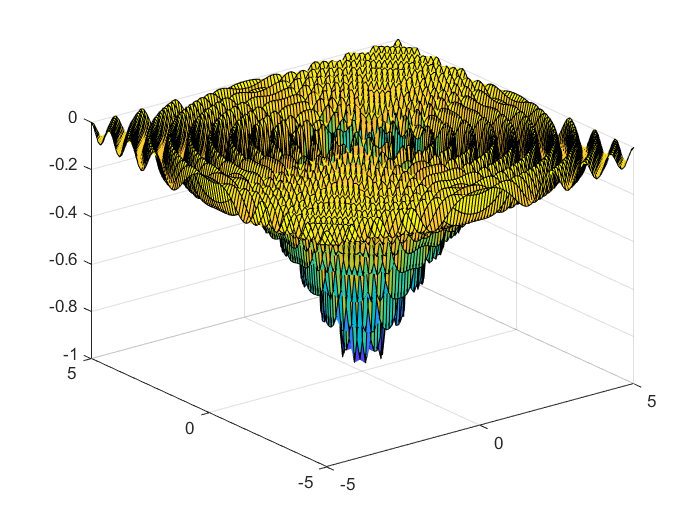

[X,Y] = meshgrid(x,y);
surf(x,y,f(X,Y))
hold on

## Algoritmos Geneticos (Toolbox) 

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


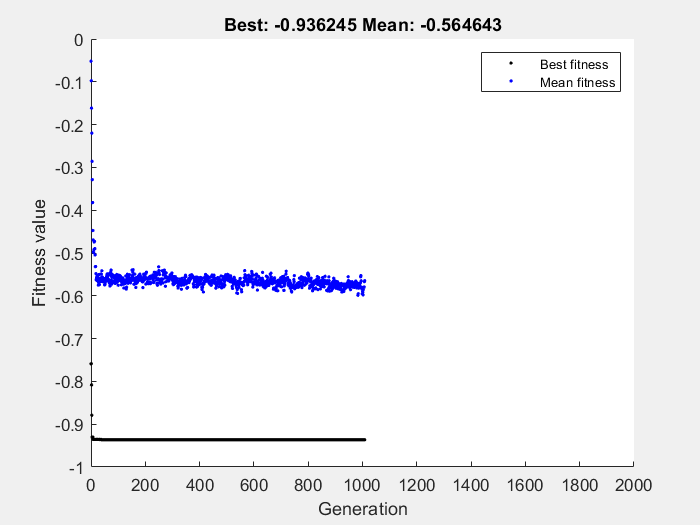

solution =    -0.3347   -0.3981


objetivevalue = -0.9362

fun = @(x) f(x(1), x(2));

rng shuffle;

options = optimoptions('ga','PlotFcn',@gaplotbestf,...
    'MaxGenerations', 2000,...
    "PopulationSize", 1000,...
    "FunctionTolerance",1E-6, ...
    "MaxStallGenerations",1000, ...
    "UseVectorized",false);
[solution, objetivevalue] = ga(fun,2, ...
    [],[],[],[],[],[],[], options)

## Algoritmos Generticos (Manual) 

clear;

% Cantidad de iteraciones
N = 50;
ciclos = 500;
mutacion = 0.7;
razonmutacion = 0.975;

% Prealocar
y_min = zeros(ciclos,1); %Ir guardando valor min

% Generacion de la poblacion inicial
rng('default');
pd = makedist('Uniform',limits(1),limits(2));
hijomutado = random(pd,N,N);

% % Funcion
% f1 = @(x) (x.^2 + x).*cos(x);
% % f1 = @(x) -(x+7).^2;
% xs = -10:0.1:10;

for nn=1:ciclos
    
    % Evaluacion de la funcion (fitness)
    y = f1(hijomutado);
    
    % PLOTS
    plot(xs, f1(xs), hijomutado, y, '.');
    pause(0.1)
    
    % Ordena de mejor a peor
    [Individuos,D] = seleccion_CR(hijomutado,exp(y));
    
    for ii=1:N
        % Seleccion
        p = randsample(N,2,true,Individuos(:,D+1));
        padre1 = Individuos(p(1),1:D);
        padre2 = Individuos(p(2),1:D);

      
        % Cruza
        [hijo] = cruza_CR(padre1, padre2,N);
        
        % Mutacion
        hijomutado = mutacion_CR(hijo,mutacion);
        
        % De regreso a decimal
        %x(ii) = ((-1)^(hijomutado(1))) * bi2de(hijomutado(2:D+1)) ./ (10^exponente);
        
        % Condicion para quedarse dentro del dominio de busqueda
        if abs(hijomutado(1))>10
            delx = abs(10 - abs(hijomutado(1)));
            hijomutado(1) = sign(hijomutado(1))*10 - sign(hijomutado(1))*delx;
        end

    end
    
    % Cambio en la mutacion
    mutacion = razonmutacion * mutacion;
    y_min(nn) = max(y);
end

hijomutado(end), y_min(end), mean(hijomutado), mean(y_min)

plot(y_min)

## Funciones

function [M,D] = seleccion_CR(x, y)
% x es una matriz con todos los candidatos(poblacion) y y es un vector con
% la funcion evaluada en cada x(i). 

    D = size(x,2);

    % Probabilidades
    Prob_y = y./(sum(y)); %+ 1 .* (sum(y)==0)) + (1/size(x,1)) .* (sum(y)==0);
    
    % Llenamos la matriz IndividuosBinarios
    Matriz = zeros(size(x,1), size(x,2)+1);
    Matriz(:,1:D) = x;
    Matriz(:,D+1) = Prob_y(:,1);
    
    % Acomoda la matriz y realiza una suma acumulada para sus probabilidades
    % respectivas
    M = sortrows(Matriz,D+1);
    M(:,D+1) = cumsum(M(:,D+1));
    
end

function [hijo] = cruza_CR(padre1, padre2,N)
% Licuado
    rng("shuffle")
    pd=makedist("Uniform",0,N); %Cambiar a que sea vector para hacerlo mas robusto
    bet = random(pd,1,N);       %Cambiar a que sea vector para hacerlo mas robusto
        % random(pd,1,N) interesante N = length(padre1)
    
    hijo = bet .* padre1 + (1-bet) .* padre2;
    
end

function [mutado] = mutacion_CR(hijo,gam)

    rng("shuffle")
    pd=makedist("Normal",0,1); 
    Y = random(pd,1,1);   %Cambiar a que sea vector para hacerlo mas robusto.
    % random(pd,1,N) interesante N = length(hijo)
    
    mutado = hijo + gam .* Y; 

end


## Funciones

function hijo = cruzareal(padre1, padre2)
    n = length(padre1);
    bet = rand(n,1);
    hijo = bet .* padre1 + (1-bet).*padre2;
end

function M = seleccionreal(x,y)
    % x es una matriz con las soluciones.  Cada columna es una variable,
    % mientras que los renglones son los distintos N aleatorios

    D = size(x,2);

    % Probabilidades
    Prob_y = y./(sum(y) + 1 .* (sum(y)==0)) + (1/size(x,1)) .* (sum(y)==0);
    
    % Llenamos la matriz IndividuosBinarios
    Matriz = zeros(size(x,1), size(x,2)+1);
    Matriz(:,1:D) = x;
    Matriz(:,D+1) = (Prob_y);
    
    % Acomoda la matriz y realiza una suma acumulada para sus probabilidades
    % respectivas
    M = sortrows(Matriz,D+1);
    M(:,D+1) = cumsum(M(:,D+1));
end

function mutado = mutacionreal(individuo, mutacion)
    % Mutación de la cadena real
    D = length(individuo);
    mutado = individuo + mutacion*randn(D,1);
end